# Simulation 1 Companion

## MATLAB Onramp

In order to complete Simulation 1 you will should complete the following modules from the [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted).

- [Commands](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=2)

- [MATLAB Desktop and Editor](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=3)

- [Vectors and Matrices](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=4)

- [Array Indexing and Modification](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=5)

- [Array Calculations](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=6)

- [Function Calls](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=7)

- [Documentation](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=8)

- [Plots](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=9)

It will be assumed that you are familiar with the content of these modules.

## Plotting Example

Let us use MATLAB to plot sine and cosine.

First we create an x-axis from $0$ to $2\pi$ with step size $\pi/24$. We do this by creating a vector called x containing these values. You should have seen this in the [Vectors and Matrices](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=4) modules. 

Uncomment by deleting the percent sign at the start of the line and then select Run Section to see the output. 

*Note: while the percent sign is present the code in that line will be ignored.*

x = 0:pi/24:2*pi

Next we obtain the values of $\sin(x)$ and $\cos(x)$ for each $x$ in the row vector we just created. We do this by creating two vectors. 

Again uncomment by deleting the percent sign and then select Run Section to see the output. 

*Note: I will now longer give you this instruction but you should continue uncommenting and selecting Run Section as you proceed.*

y1 = sin(x) % contains sin(x) for each value in the row vector x
y2 = cos(x) % contains cos(x) for each value in the row vector x

Next we plot $y = \sin(x)$ and note a viewing window will automatically be selected. 

plot(x,y1)

I would prefer having a grid.

grid

I want to adjust the viewing window so that $x$ is between $0$ and $2\pi$ and $y$ is between $-1.25$ and $1.25$. 

*Note: if you want more details on a function, like the *`axis`* function below, search for it in the Matlab documentation.*

axis([0 2*pi -1.25 1.25])

Next we label the $x$-axis `x` and the $y$-axis `y`.

xlabel('x')
ylabel('y')

If we were to now enter `plot(x,y2)` then the plot would be placed on another grid. You can see this by running after only uncommenting `plot(x,y2)` below. To ensure our plot is placed on the same grid, we first enter `hold on `to hold to the same grid.

hold on
plot(x,y2)

Now we add a legend. We enter the labels in the order that the graphs were plotted. 

legend('y1','y2')

Since we are done with this grid we type `hold off` to conclude the `hold on` that we had activated earlier.

hold off

To summarize: what we would have entered into our .m file is as follows. 

*Note: the semicolon at the end of a line hides the output of the command. I do not care to see the contents of the vectors *`x,` `y1,` `y2`* printed on the screen. I only care to see their graphs. *

x = 0:pi/24:2*pi;

y1 = sin(x);
y2 = cos(x);

plot(x,y1)

grid
axis([0 2*pi -1.25 1.25])
xlabel('x')
ylabel('y')

hold on
plot(x,y2)

legend('y1','y2')
hold off

## Modified Plotting Example

Suppose we instead want to plot graphs of $y = x^2e^{-x}$ and $y = 1/(x+1)$ in two separate axes but such that the output will be placed in particular positions in the same figure.

We begin by redefining `x` and `y1` and `y2`. 

*Note: we use *`.*`* instead of *`*`* for multiplication, *`./`* instead of *`/` *for division, and *`.^2`* instead of *`^2`* for squaring. The *`.`* indicates that the operation is ****pointwise****. This ensures that for example when we write *`x.^2`* we are in fact squaring each element in the array *`x`*. If you type *`x^2`* you are instructing Matlab to execute a ****matrix multiplication**** which is not the same as ****pointwise multiplication. ****In fact, in this icase it will lead to an error.*

x = linspace(0,10,101) % you saw the meaning of this in the Matlab Onramp

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



y1 = x.^2 .* exp(-x)

y1 =          0    0.0090    0.0327    0.0667    0.1073    0.1516    0.1976    0.2433    0.2876    0.3293    0.3679    0.4028    0.4337    0.4606    0.4833    0.5020    0.5169    0.5280    0.5356    0.5399    0.5413    0.5400    0.5363    0.5304    0.5225    0.5130    0.5021    0.4899    0.4768    0.4627    0.4481    0.4329    0.4174    0.4017    0.3858    0.3699    0.3541    0.3385    0.3230    0.3079    0.2931    0.2786    0.2645    0.2509    0.2377    0.2250    0.2127    0.2009    0.1896    0.1788


y2 = 1./(x+1)

y2 =     1.0000    0.9091    0.8333    0.7692    0.7143    0.6667    0.6250    0.5882    0.5556    0.5263    0.5000    0.4762    0.4545    0.4348    0.4167    0.4000    0.3846    0.3704    0.3571    0.3448    0.3333    0.3226    0.3125    0.3030    0.2941    0.2857    0.2778    0.2703    0.2632    0.2564    0.2500    0.2439    0.2381    0.2326    0.2273    0.2222    0.2174    0.2128    0.2083    0.2041    0.2000    0.1961    0.1923    0.1887    0.1852    0.1818    0.1786    0.1754    0.1724    0.1695


We next create a figure window that will contain our two plots.

figure

We divide our figure into 2 rows and 1 column, then create axes in position 1: the 1st column of the 1st row of our figure.

*Note: remember to look at Matlab documentation whenever you do not understand the content of a function, like the *`subplot`* function below.*

subplot(2,1,1)

We plot `y1` and make it red and dashed using `'--r'`. We create a grid and label the axes.

plot(x,y1,'--r')
grid
xlabel('x')
ylabel('x^2e^{-x}')

Next we create axes in position 2: the 1st column of the second row.

subplot(2,1,2)

We plot `y1` and make it magenta using `'m'` and extra thick, with a thickness of 2 points using` 'LineWidth',2`. We create a grid and label the axes.

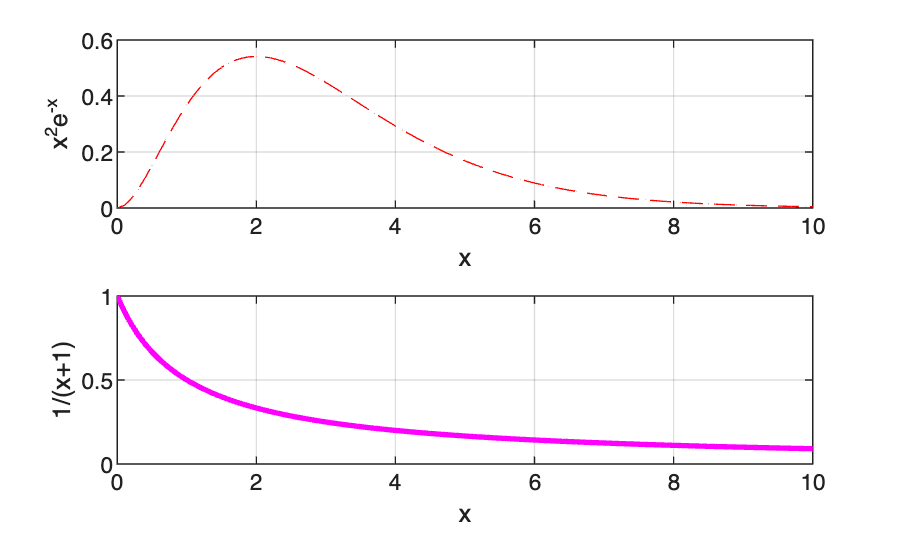

plot(x,y2,'m','LineWidth',2)
grid
xlabel('x')
ylabel('1/(x+1)')

We have now plotted two graphs in specified positions in the same figure. Now we clear the figure using `clf` so we can begin a new figure in the next example.

clf

## Matrices Example

Let us construct and modify arrays, aka **matrices**. It goes without saying that you should have completed the Matlab Onramp modules listed at the top in order to understand the basics in order to proceed. 

Let us generate the matrix $A = \left(\begin{array}{cccc}1&3&6&4\\3&8&0&1\\2&4&7&9\end{array}\right)$.

A = [1 3 6 4;3 8 0 1; 2 4 7 9]

A =      1     3     6     4
     3     8     0     1
     2     4     7     9


Let us confirm that its size is $3 \times 4$ i.e. 3 rows and 4 columns.

size(A)

ans =      3     4


Let us convert entry $A_{13}$ (row 1 column 3) to 0.

A(1,3) = 0

A =      1     3     0     4
     3     8     0     1
     2     4     7     9


And let us take the square root of every entry in the last column:

A(:,end) = sqrt(A(:,end))

A =      1     3     0     2
     3     8     0     1
     2     4     7     3


And let us take the third row and multiply it pointwise by the last row.

A(3,:) = A(3,:).*A(end,:)

A =      1     3     0     2
     3     8     0     1
     4    16    49     9


Now let us delete the third column to obtain a square $3 \times 3$ matrix.

A(:,3) = []

A =      1     3     2
     3     8     1
     4    16     9


Next let us swap the entries $A_{32}$ and $A_{33}$.

temp = A(3,2); % temporarily save A(3,2) as the variable temp and conceal the output
A(3,2) = A(3,3); % replace A(3,2) with A(3,3) and conceal the output
A(3,3) = temp % replace A(3,3) with the old value of A(3,2)

A =      1     3     2
     3     8     1
     4     9    16


Lastly let us plot the first row against the last row as a scatter plot. A scatter plot will not include connecting lines between data points.

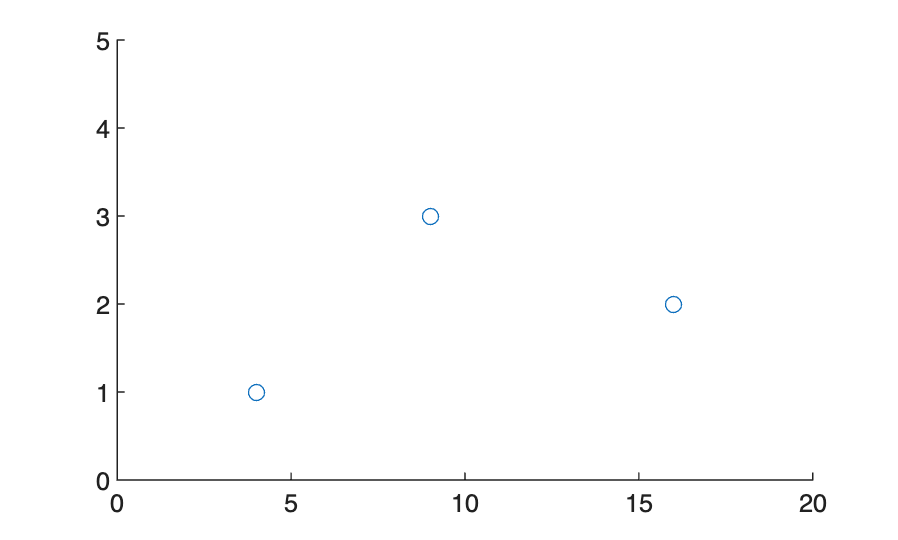

scatter(A(end,:),A(1,:))
axis([0 20 0 5])